%{
Program to inpaint images using low rank completion methods
Harsh Shah and Pranava Singhal 
%}

addpath '.\MMread';
rng(73);

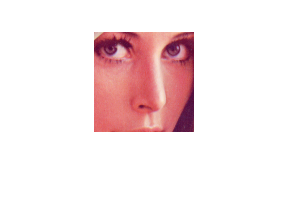


img = imread('data/lenna.png');
img = double(img(250:349,250:349, :))/255;
imshow(img)



H = size(img,1);
W = size(img,2);
block_size = 5;

obs = 0.7;
mask_1 = binornd(1,obs, [floor(H/block_size),floor(W/block_size)]);
mask = zeros(H,W);
for i = block_size:block_size:H
    for j = block_size:block_size:W
        mask(i-block_size+1:i,j-block_size+1:j) = mask_1(floor(i/block_size),floor(j/block_size));
    end
end

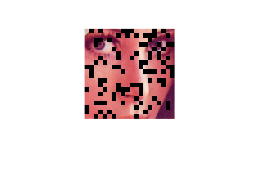

img_f = (img);
imshow(img_f.*mask)

patch_size = 8;
stride = 1;
img_patches = generatePatches_overlapping(img, patch_size, stride);
mask_patches = generatePatches_overlapping(mask, patch_size, stride);


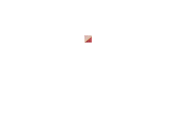

imshow(img_patches(:,:,:,1));

img_concat = concatPatches(img_patches);
mask_concat = concatPatches(mask_patches);
mu = 1;
frame = zeros(size(img_concat));
for c = 1:3
    frame(:,:,c) = fixed_point_minimization(mask_concat, img_concat(:,:,c), mu,-1,-1,-1);
end

htg_sensei
htg_sensei
htg_sensei


imshow(frame);

imshow(img_concat);

x_patches = (W - patch_size + stride)/stride;
y_patches = (H - patch_size + stride)/stride;
num_channels = size(frame, 3);
num_patches = size(frame, 2);


frame_reshaped = permute(reshape(permute(frame, [1 3 2]), patch_size, patch_size, num_channels, num_patches), [4 1 2 3]);

frame_recons = imageReconstruction_overlapping(frame_reshaped, x_patches, y_patches, stride);

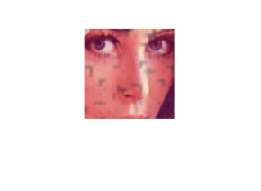

imshow(frame_recons)

function result = concatPatches(patches)
    patch_size = size(patches,1);
    num_patches = size(patches,4);
    num_channels = size(patches,3);
    columns = reshape(patches, [patch_size*patch_size, num_channels, num_patches]);
    colcel = num2cell(columns,[1,2]);
    concatenated = cat(3,colcel{:});
    result = permute(concatenated,[1,3,2]);
end

function result = imageReconstruction_overlapping(all_patches, x_patches, y_patches, stride)
    all_patches_size = size(all_patches);
    patch_dim = all_patches_size(2);
    T = all_patches_size(4);
    height = patch_dim + stride*(y_patches-1);
    width = patch_dim + stride*(x_patches-1);
    
    reconstruction = zeros(height, width, T);
    count_mat = zeros(height, width, T);
    for i = 1:x_patches
        for j = 1:y_patches
            reconstruction((j-1)*stride+1:(j-1)*stride+patch_dim, (i-1)*stride+1:(i-1)*stride+patch_dim, :) = reconstruction((j-1)*stride+1:(j-1)*stride+patch_dim, (i-1)*stride+1:(i-1)*stride+patch_dim, :) + squeeze(all_patches((i-1)*y_patches + j, :, :, :));
            count_mat((j-1)*stride+1:(j-1)*stride+patch_dim, (i-1)*stride+1:(i-1)*stride+patch_dim, :) = count_mat((j-1)*stride+1:(j-1)*stride+patch_dim, (i-1)*stride+1:(i-1)*stride+patch_dim, :) + ones(patch_dim, patch_dim, T);
        end
    end
    result = reconstruction./count_mat;  
end
function patches = generatePatches_overlapping(image, patch_dim, stride)
    height = size(image, 1);
    width = size(image, 2);
    T = size(image, 3);
    assert(rem(height-patch_dim, stride) == 0);
    assert(rem(width-patch_dim, stride) == 0);
    blocks_x = (width-patch_dim)/stride+1;
    blocks_y = (height-patch_dim)/stride+1;
    
    patches = zeros(patch_dim, patch_dim, T, blocks_x*blocks_y);

    for i=1:blocks_x
        for j=1:blocks_y
            patch = image((j-1)*stride+1 : patch_dim+(j-1)*stride,(i-1)*stride+1 : patch_dim+(i-1)*stride, :);
            patches(:, :, :, (i-1)*blocks_y+j) = patch;
        end
    end
end

function result = soft_shrinkage(A, tau)
    [U, S, V] = svd(A);
    S(S>0) = S(S>0)-tau;
    S(S<0) = 0;
    result = U*S*V';
end

function result = fixed_point_minimization(P, GT, mu, tau, max_iterations, threshold)
    n1 = size(P, 1);
    n2 = size(P, 2);
    % TODO: find appropriate mu
    if max_iterations == -1
        max_iterations = 100;
    end
    if tau == -1
        tau = 1.5;
    end
    if threshold == -1
        threshold = 0.0001;
    end
    
    curr_iter = 0;
    Q_new = zeros(n1, n2);
    Q_prev = zeros(n1, n2);
    R = zeros(n1, n2);
    converged = false;
    convergence_num = 5; 
    curr_conv = 0;
    while curr_iter < max_iterations && not(converged)
        R = Q_prev - tau*(P.*(Q_prev - GT));
        Q_new = soft_shrinkage(R, tau*mu);
        if norm(Q_prev - Q_new, "fro") < threshold && norm(P.*(Q_prev - GT), "fro") < threshold
            curr_conv = curr_conv + 1;
            disp("converged")
        end
        if curr_conv == convergence_num
            converged = true;
        end
        Q_prev = Q_new;
        curr_iter = curr_iter + 1;
    end
    disp("htg_sensei");
    result = Q_new;
end
